## Procesamiento de datos

data = readmatrix('Flujo_delta_25a50.xlsx','Range','A377:C1471')

data =    30.0245   25.0000   20.5266
   30.0510   25.0000   20.2205
   30.0775   25.0000   20.4756
   30.1040   25.0000   20.1695
   30.1305   25.0000   20.6797
   30.1570   25.0000   20.1184
   30.1835   25.0000   20.3225
   30.2100   25.0000   19.9653
   30.2365   25.0000   20.2205
   30.2630   25.0000   19.5571


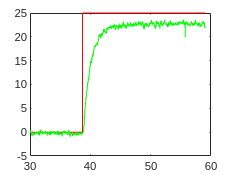

%data = readmatrix('Flujo_delta_25a50_sin_ruido.xlsx')

%data = readmatrix('Flujo_delta_25a50.xlsx')


t = data(:,1);
u = data(:,2);
y = data(:,3);


yn = y - mean(y(1:10));
un = u - mean(u(1:10));

figure(1);
plot(t, un, 'r', t, yn, 'g');

%figure(2);
%plot(t, u, 'r', t, y, 'g');

## System Identification Tool

%systemIdentification

## Identificación 123c Alfaro Primer orden con retardo

yf = mean(yn(1085:1095))

yf = 22.5397

yi = mean(yn(1:10))

yi = -3.5527e-15


uf = mean(un(1085:1095))

uf = 25

ui = mean(un(1:10)) 

ui = 0


deltay = yf - yi

deltay = 22.5397


deltau = uf - ui

deltau = 25


K = deltay/deltau

K = 0.9016


y25 = 0.25*deltay

y25 = 5.6349

y50 = 0.50*deltay;
y75 = 0.75*deltay;

y25_0 = find(y >= y25, 1)  

y25_0 = 1




T = 0.9102*(y75 - y25)

T = 10.2578

L = 1.2620*y25 - 0.2620*y75

L = 2.6822